%ATTEMPTS
%1.Using additional control points
%2.Taking additional points along original curve as control points
%3.Linearly compacting the replanner time domain
%4.Warping the replanner time domain by an inverse normal distribution
%(incocnlusive)
%5.Skipping forward in the replanner time by the additional period added to
%tmax
%FIXED issue with knots and errors from replanner
%Small gap between two positional splines is due to the fact they are
%plotted separately, as the paths should not and do not overlap

%INCLUDE THESE GRAPHS - PARTICULARLY THE ONE WITH THE ORIGINAL AND
%REPLANNED

%MAKE THICKER TRENDS
%'CONSERVING DERIVATIVES OF MOTION CONTINUITY AND SMOOTHNESS

VMagMAT = absBS(VelMAT);
AMagMAT = absBS(AccMAT);
JMagMAT = absBS(JerkMAT);
SMagMAT = absBS(SnapMAT);
cVMagMAT = absBS(cVelMAT);
cAMagMAT = absBS(cAccMAT);
cJMagMAT = absBS(cJerkMAT);
cSMagMAT = absBS(cSnapMAT);

len = height(PosMAT);
intrpt = round(PFact*len);

tlin = linspace(0, intrpt, intrpt).';
tlin2 = linspace(intrpt+1, height(cPosMAT)+intrpt+1, height(cPosMAT)).';
pause = intrpt*pstep;

VCombMAT = [VMagMAT(1:intrpt,1)*pstep, VMagMAT(1:intrpt,2); cVMagMAT(:,1)*pstep+intrpt*pstep, cVMagMAT(:,2)];
ACombMAT = [tlin, AMagMAT(1:intrpt,2); tlin2, cAMagMAT(:,2)];
JCombMAT = [tlin, JMagMAT(1:intrpt,2); tlin2, cJMagMAT(:,2)];
SCombMAT = [tlin, SMagMAT(1:intrpt,2); tlin2, cSMagMAT(:,2)];

PosMAT(intrpt,:)

ans =    68.0413   43.7933


cPosMAT(1,:)

ans =    68.0413   43.7933


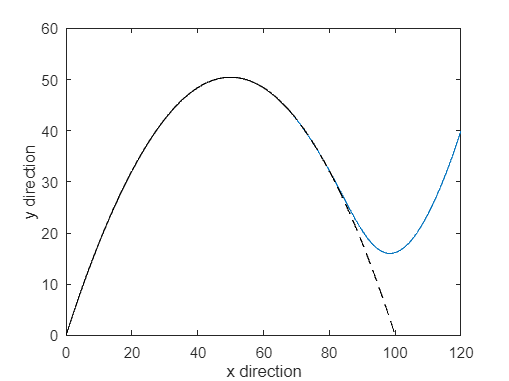


plot(PosMAT(1:intrpt,1),PosMAT(1:intrpt,2), 'Color', "black")
hold on
plot(cPosMAT(:,1),cPosMAT(:,2), 'Color', "#0072BD")
plot(PosMAT(Pauseloc:end,1), PosMAT(Pauseloc:end,2), '--', 'Color', 'black')
xlabel('x direction')
ylabel('y direction')
hold off

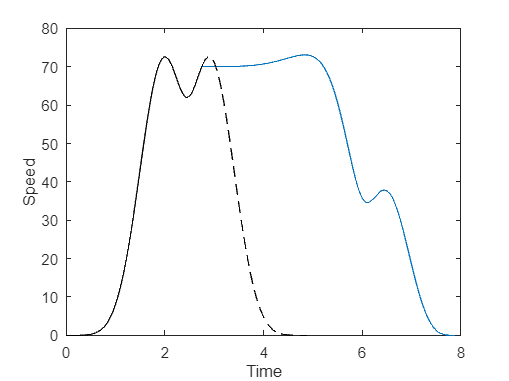

plot(VCombMAT(1:intrpt,1),VCombMAT(1:intrpt,2), 'Color', "black")
hold on
plot(VCombMAT(intrpt:end,1),VCombMAT(intrpt:end,2), 'Color', "#0072BD")
plot(VMagMAT(Pauseloc:end,1)*pstep, VMagMAT(Pauseloc:end,2), '--', 'Color', 'black')
xlabel('Time')
ylabel('Speed')
hold off

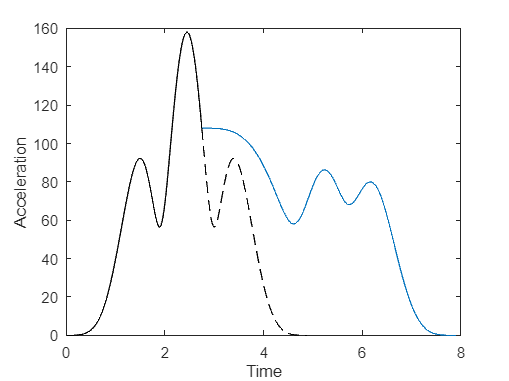

plot(ACombMAT(1:intrpt,1)*pstep,ACombMAT(1:intrpt,2), 'Color', "black")
hold on
plot(ACombMAT(intrpt:end,1)*pstep,ACombMAT(intrpt:end,2), 'Color', "#0072BD")
plot(AMagMAT(Pauseloc:end,1)*pstep, AMagMAT(Pauseloc:end,2), '--', 'Color', 'black')
xlabel('Time')
ylabel('Acceleration')
hold off

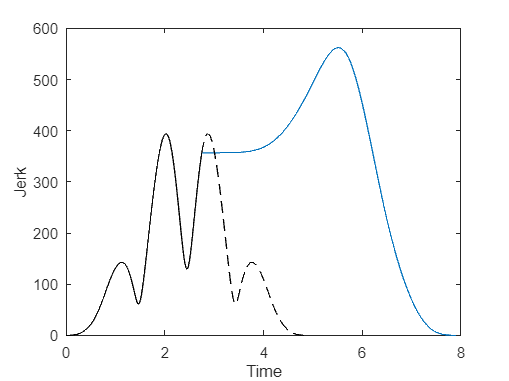

plot(JCombMAT(1:intrpt,1)*pstep,JCombMAT(1:intrpt,2), 'Color', "black")
hold on
plot(JCombMAT(intrpt:end,1)*pstep,JCombMAT(intrpt:end,2), 'Color', "#0072BD")
plot(JMagMAT(Pauseloc:end,1)*pstep, JMagMAT(Pauseloc:end,2), '--', 'Color', 'black')
xlabel('Time')
ylabel('Jerk')
hold off

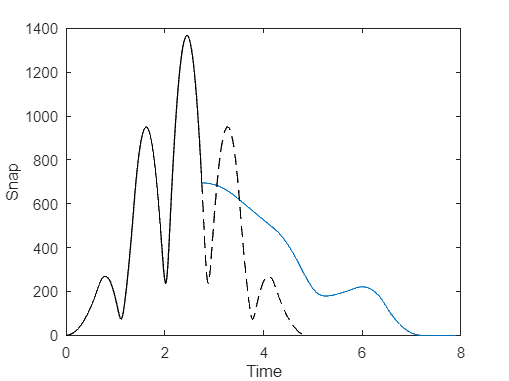

plot(SCombMAT(1:intrpt,1)*pstep,SCombMAT(1:intrpt,2), 'Color', "black")
hold on
plot(SCombMAT(intrpt:end,1)*pstep,SCombMAT(intrpt:end,2), 'Color', "#0072BD")
plot(SMagMAT(Pauseloc:end,1)*pstep, SMagMAT(Pauseloc:end,2), '--', 'Color', 'black')
xlabel('Time')
ylabel('Snap')
%plot(SMagMAT(intrpt:end,1),SMagMAT(intrpt:end,2))
hold off

function MagMAT = absBS(Pos)
    N = length(Pos.');
    MagMAT = [];
    for i = 1:1:N
        X = Pos(i,1);
        Y = Pos(i,2);
        abs = sqrt(X^2+Y^2);
        MagMAT = [MagMAT; i, abs];
    end
end